## Homework 08 Root Finding

### 1. Use zero-, first-, second- and third-order Taylor series expansions to predict$f\left(2\right)$

### 
$$f\left(x\right)=25x^3 -6x^2 +7x-88$$


%Initialization Workspace
clear
clc

%Initial Function
syms x
function_x(x) = 25*(x^3) - 6*(x^2) + 7*x - 88

$$function\_x(x) = 25\,x^{3}-6\,x^{2}+7\,x-88$$

function_x(1)

$$ans = -62$$

function_x(2)

$$ans = 102$$

Using a base point at x = 1 and step size = 0.1, 0.5, 1 with **Backward Divided Difference.**


$$f^{\left(n\right)} \left(x\right)=\frac{\bigtriangledown_h^n \left\lbrack f\right\rbrack \left(x\right)}{h^n }=$$
 
$$\frac{1}{h^n }$$
 
$$\sum_{k=0}^n {\left(-1\right)}^k$$

$${n\choose k}$$

$$f\left(x-kh\right),$$


%Initial Condition
STEP_SIZE = [0.1, 0.5, 1];
x_i = 1;
x_target = 2;

Calculate the error for each of the Taylor series expansions


$$f\left(x_{i+1} \right)=\sum_{n=0}^{\infty } \frac{f^{\left(n\right)} \left(x_i \right)}{n!}{\left(x_{i+1} -x_i \right)}^n ,$$


%Error
syms trueValue approximationValue
error(trueValue,approximationValue) = ((trueValue - approximationValue)/trueValue);


$$\mathrm{error}=\frac{\mathrm{trueV}\mathrm{alue}-\mathrm{approximatedV}\mathrm{alue}}{\mathrm{trueV}\mathrm{alue}}$$


#### Zero-Order Taylor Series Expansion

#### 
$$f\left(x_{i+1} \right)\cong f\left(x_i \right)$$


clear term_taylorSeries term_dividedDifference_backward
order = 0;

for i = 1:size(STEP_SIZE,2)
    h = STEP_SIZE(i);
    
    %Taylor Series
    for n = 0:order
        
        %Divided Difference Backward
        for k = 0:n
            term_dividedDifference_backward(k+1) = (((-1)^k) * nchoosek(n,k) * function_x(x_i - k*h));
        end
        dividedDifference_backward_order(n+1) = sum(term_dividedDifference_backward) / (h^n);
        %Divided Difference Backward END
        
        term_taylorSeries(n+1) = (dividedDifference_backward_order(n+1) / factorial(n)) * ((x_target - x_i)^n);
    end
    approximationValue_order0(i) = sum(term_taylorSeries);
    %Taylor Series END
    
    fprintf('Approximation Value (Taylor + Backward Zero-Order Step %0.2f) :%0.2f\n', ...
        STEP_SIZE(i), approximationValue_order0(i))
end

Approximation Value (Taylor + Backward Zero-Order Step 0.10) :-62.00
Approximation Value (Taylor + Backward Zero-Order Step 0.50) :-62.00
Approximation Value (Taylor + Backward Zero-Order Step 1.00) :-62.00


order = 0;

for i = 1:size(STEP_SIZE,2)
    h = STEP_SIZE(i);
    
    %Taylor Series
    clear term_taylorSeries dividedDifference_backward_order
    for n = 0:order
    
        %Divided Difference Backward
        clear term_dividedDifference_backward
        for k = 0:n
            term_dividedDifference_backward(k+1) = (((-1)^k) * nchoosek(n,k) * function_x(x_i - k*h));
        end
        dividedDifference_backward_order(n+1) = sum(term_dividedDifference_backward) / (h^n);
        %Divided Difference Backward END
        
        term_taylorSeries(n+1) = ( ...
            dividedDifference_backward_order(n+1) / factorial(n)) * ((x_target - x_i)^n);
    end
    approximationValue_order0(i) = sum(term_taylorSeries);
    %Taylor Series END
    
    fprintf('Approximation Value (Taylor + Backward Zero-Order Step %0.2f) :%0.2f\n', ...
        STEP_SIZE(i), approximationValue_order0(i))
end

Approximation Value (Taylor + Backward Zero-Order Step 0.10) :-62.00
Approximation Value (Taylor + Backward Zero-Order Step 0.50) :-62.00
Approximation Value (Taylor + Backward Zero-Order Step 1.00) :-62.00


#### One-Order Taylor Series Expansion

#### 
$$f\left(x_{i+1} \right)\cong f\left(x_i \right)+f^{\prime } \left(x_i \right)\left(x_{i+1} -x_i \right)$$


order = 1;

for i = 1:size(STEP_SIZE,2)
    h = STEP_SIZE(i);
    
    %Taylor Series
    clear term_taylorSeries dividedDifference_backward_order
    for n = 0:order
    
        %Divided Difference Backward
        clear term_dividedDifference_backward
        for k = 0:n
            term_dividedDifference_backward(k+1) = (((-1)^k) * nchoosek(n,k) * function_x(x_i - k*h));
        end
        dividedDifference_backward_order(n+1) = sum(term_dividedDifference_backward) / (h^n);
        %Divided Difference Backward END
        
        term_taylorSeries(n+1) = ( ...
            dividedDifference_backward_order(n+1) / factorial(n)) * ((x_target - x_i)^n);
    end
    approximationValue_order1(i) = sum(term_taylorSeries);
    %Taylor Series END
    
    fprintf('Approximation Value (Taylor + Backward One-Order Step %0.2f) :%0.2f\n', ...
        STEP_SIZE(i), approximationValue_order1(i))
end

Approximation Value (Taylor + Backward One-Order Step 0.10) :1.35
Approximation Value (Taylor + Backward One-Order Step 0.50) :-20.25
Approximation Value (Taylor + Backward One-Order Step 1.00) :-36.00


#### Second-Order Taylor Series Expansion

#### 
$$f\left(x_{i+1} \right)\cong f\left(x_i \right)+f^{\prime } \left(x_i \right)\left(x_{i+1} -x_i \right)+\frac{f^{\prime \prime } \left(x_i \right){\left(x_{i+1} -x_i \right)}^2 }{2!}$$


order = 2;

for i = 1:size(STEP_SIZE,2)
    h = STEP_SIZE(i);
    
    %Taylor Series
    clear term_taylorSeries dividedDifference_backward_order
    for n = 0:order
    
        %Divided Difference Backward
        clear term_dividedDifference_backward
        for k = 0:n
            term_dividedDifference_backward(k+1) = (((-1)^k) * nchoosek(n,k) * function_x(x_i - k*h));
        end
        dividedDifference_backward_order(n+1) = sum(term_dividedDifference_backward) / (h^n);
        %Divided Difference Backward END
        
        term_taylorSeries(n+1) = ( ...
            dividedDifference_backward_order(n+1) / factorial(n)) * ((x_target - x_i)^n);
    end
    approximationValue_order2(i) = sum(term_taylorSeries);
    %Taylor Series END
    
    fprintf('Approximation Value (Taylor + Backward Second-Order Step %0.2f) :%0.2f\n', ...
        STEP_SIZE(i), approximationValue_order2(i))
end

Approximation Value (Taylor + Backward Second-Order Step 0.10) :62.85
Approximation Value (Taylor + Backward Second-Order Step 0.50) :11.25
Approximation Value (Taylor + Backward Second-Order Step 1.00) :-42.00


#### Third-Order Taylor Series Expansion

#### 
$$f\left(x_{i+1} \right)\cong f\left(x_i \right)+f^{\prime } \left(x_i \right)\left(x_{i+1} -x_i \right)+\frac{f^{\prime \prime } \left(x_i \right){\left(x_{i+1} -x_i \right)}^2 }{2!}+\frac{{{f^{\prime } }^{\prime } }^{\prime } \left(x_i \right){\left(x_{i+1} -x_i \right)}^3 }{3!}$$


order = 3;

for i = 1:size(STEP_SIZE,2)
    h = STEP_SIZE(i);
    
    %Taylor Series
    clear term_taylorSeries dividedDifference_backward_order
    for n = 0:order
    
        %Divided Difference Backward
        clear term_dividedDifference_backward
        for k = 0:n
            term_dividedDifference_backward(k+1) = (((-1)^k) * nchoosek(n,k) * function_x(x_i - k*h));
        end
        dividedDifference_backward_order(n+1) = sum(term_dividedDifference_backward) / (h^n);
        %Divided Difference Backward END
        
        term_taylorSeries(n+1) = ( ...
            dividedDifference_backward_order(n+1) / factorial(n)) * ((x_target - x_i)^n);
    end
    approximationValue_order3(i) = sum(term_taylorSeries);
    %Taylor Series END
    
    fprintf('Approximation Value (Taylor + Backward Third Step %0.2f) :%0.2f\n', ...
        STEP_SIZE(i), approximationValue_order3(i))
end

Approximation Value (Taylor + Backward Third Step 0.10) :87.85
Approximation Value (Taylor + Backward Third Step 0.50) :36.25
Approximation Value (Taylor + Backward Third Step 1.00) :-17.00


### Summary

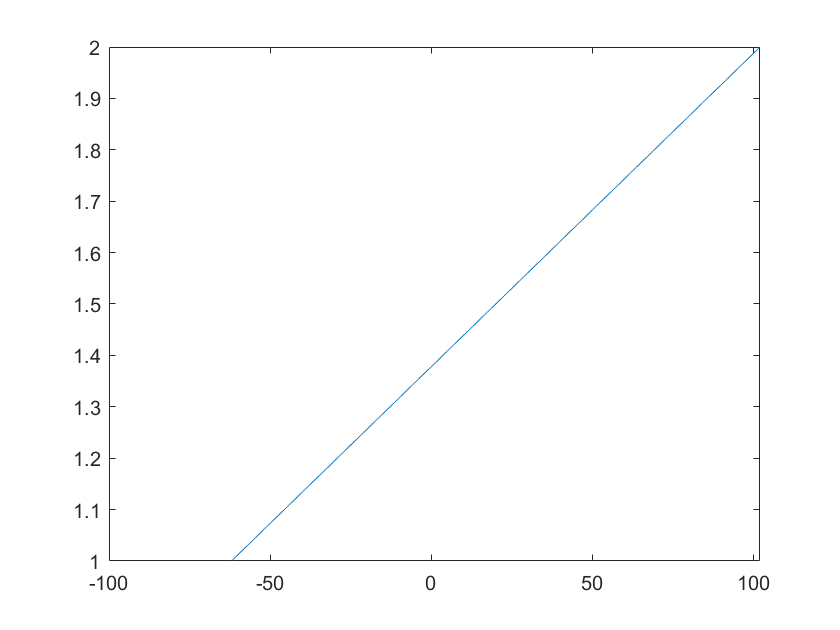

x_p = x_i:x_target;
plot(function_x(x_p),x_p)

### 2. Write a computer program that find the root of $f\left(x\right)=x^3 -3x^2 +1$ by using both bisection and false-position method in period $\left\lbrack 0,2\right\rbrack$and terminate the program when approximated

### relative error $\varepsilon_a \le 1%$  the program must generate a report file, report.txt, that shows in each

syms epsilon_t trueValue approximationValue
epsilon_t(trueValue,approximationValue) = ((trueValue - approximationValue)/trueValue)*100;

line: 

(1) the number of iterations, 

(2) an estimated root in each iteration, 

(3) the approximate relative error in each iteration.

%Initialization Workspace
clear
clc

%Initial Function
syms function_x x
function_x(x) = (x^3) - 3*(x^2) + 1

$$function\_x(x) = x^{3}-3\,x^{2}+1$$

## Appendix

%Binomial coefficient
syms n k
nchoosek(n,k);